# University of Technology Sydney

#### **Sydney, Australia**

#### **A/Prof Ricardo P. Aguilera**

**7th August 2024**

# ADC Calibration (Inputs)

clc;
clear;

## **Data Acquisition **

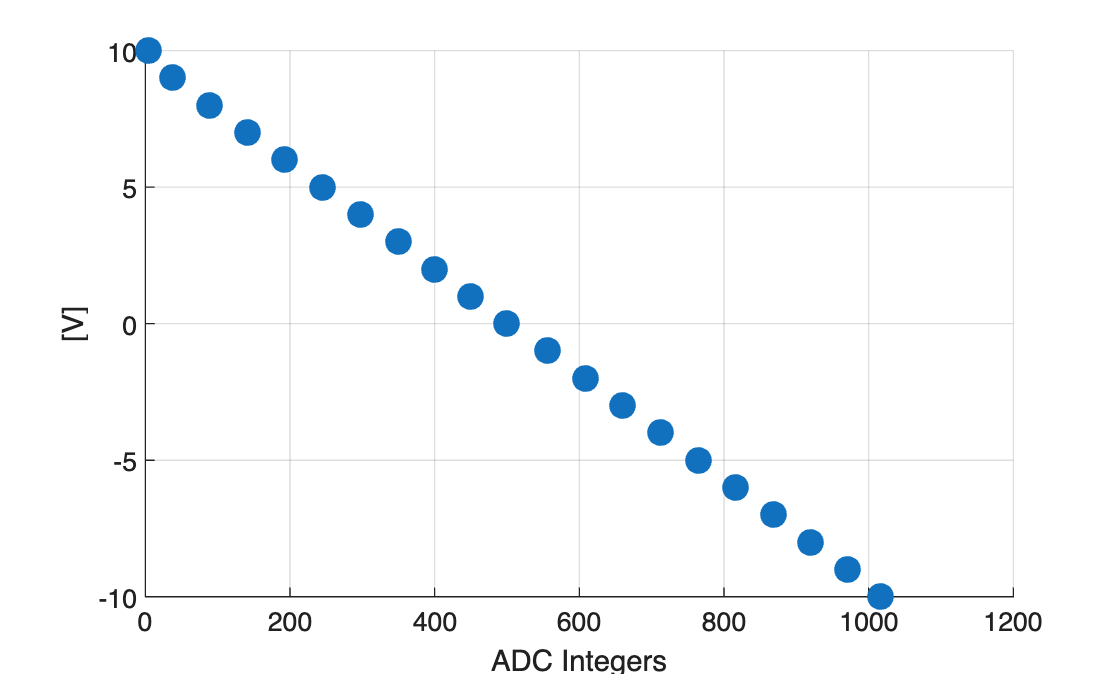

%data_calib_in1 = [ADC_Integer, Actual Voltage];
data_calib_in1 = [  500,      0;
                    450,    1;
                    400,    2
                    350, 3; 
                    297, 4;
                    245, 5;
                    193, 6;
                    141, 7;
                    89, 8; 
                    37, 9; 
                    4, 10; 
                    556, -1;
                    608, -2; 
                    660, -3;
                    712, -4;
                    765, -5;
                    816, -6;
                    868, -7;
                    920, -8;
                    971, -9;
                    1016, -10;
                    ];

x = data_calib_in1(:,1); % ADC Integer 
y = data_calib_in1(:,2); % Actual voltage

figure(1)
scatter(x,y,100,"filled")
grid
xlabel('ADC Integers')
ylabel('[V]')

## Linear Regression

p = polyfit(x,y,1);

Slope:

p1 =  p(1)

p1 = -0.0194

Intercept (offset in 'y'):

p2 =  p(2)

p2 = 9.7834

## Verification

Estimated y values:

y_fit = p1*x+p2

y_fit =     0.0905
    1.0598
    2.0290
    2.9983
    4.0258
    5.0339
    6.0419
    7.0500
    8.0580
    9.0661
    9.7058
   -0.9951
   -2.0032
   -3.0113
   -4.0193


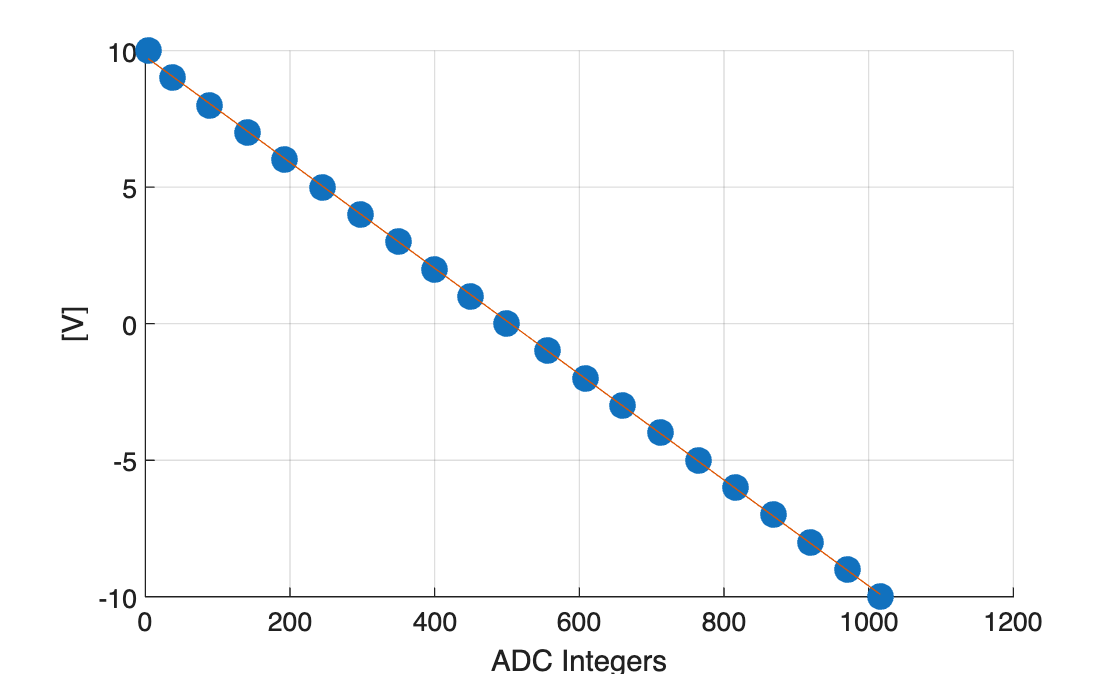

figure(2)
scatter(x,y,100,"filled")
grid
xlabel('ADC Integers')
ylabel('[V]')
hold on
plot(x,y_fit)
hold off

# PWM DAC Calibration (Outputs)

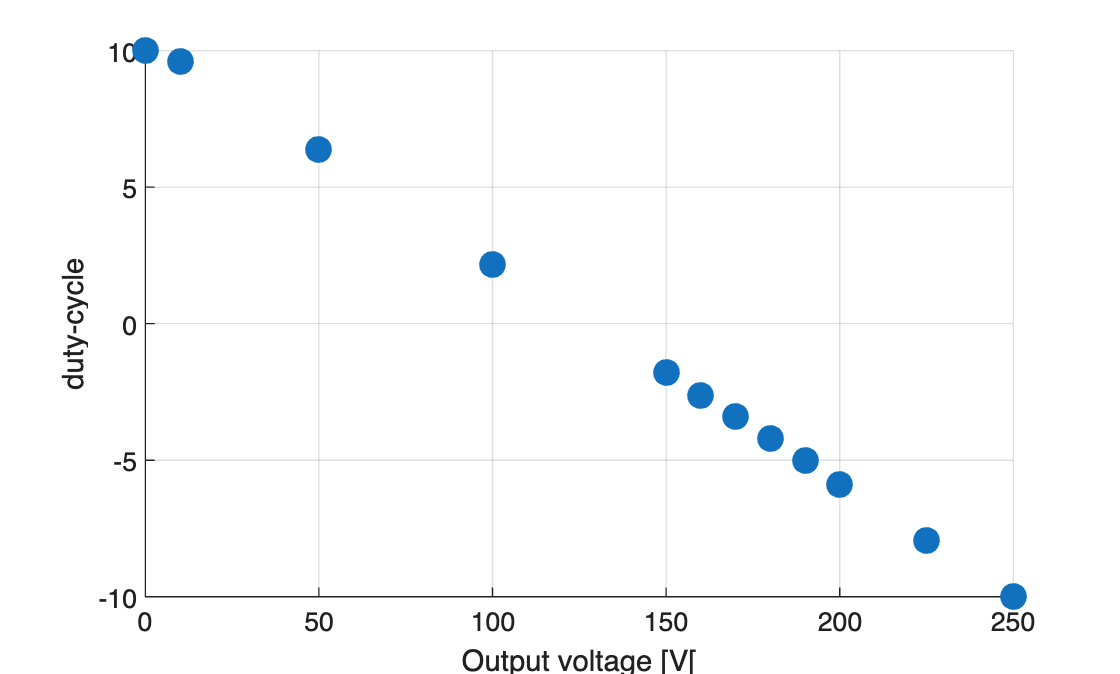

%data_calib_in1 = [Output_Voltage, duty_cycle; ]
data_calib_out1 = [  0,     10;
                     10,     9.595;
                     50,     6.37;
                     100, 2.17;
                     150, -1.79;
                     160,-2.63;
                     170, -3.41;
                     180, -4.19;
                     190, -5;
                     200, -5.89;
                     225, -7.955; 
                     250, -10; 
                     ];

x = data_calib_out1(:,1); % Actual voltage
y = data_calib_out1(:,2); % ADC Integer


figure(3)
scatter(x,y,100,"filled")
grid
xlabel('Output voltage [V[')
ylabel('duty-cycle')

## Linear Regression

p = polyfit(x,y,1);

Slope:

p1 = p(1)

p1 = -0.0807

Intercept (offset in 'y'):

p2 = p(2)

p2 = 10.2709

## Verification

Estimated y values:

y_fit = p1*x+p2

y_fit =    10.2709
    9.4639
    6.2359
    2.2008
   -1.8342
   -2.6412
   -3.4482
   -4.2552
   -5.0622
   -5.8692
   -7.8868
   -9.9043


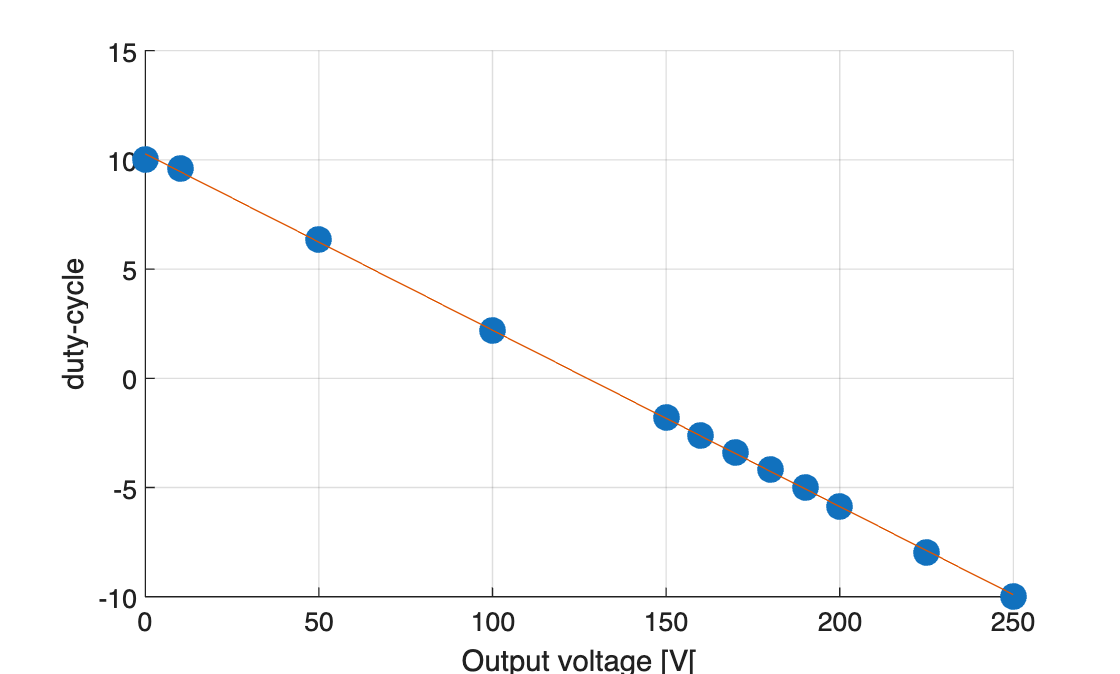

figure(2)
scatter(x,y,100,"filled")
grid
xlabel('Output voltage [V[')
ylabel('duty-cycle')
hold on
plot(x,y_fit)
hold off

## W_m1 calibration

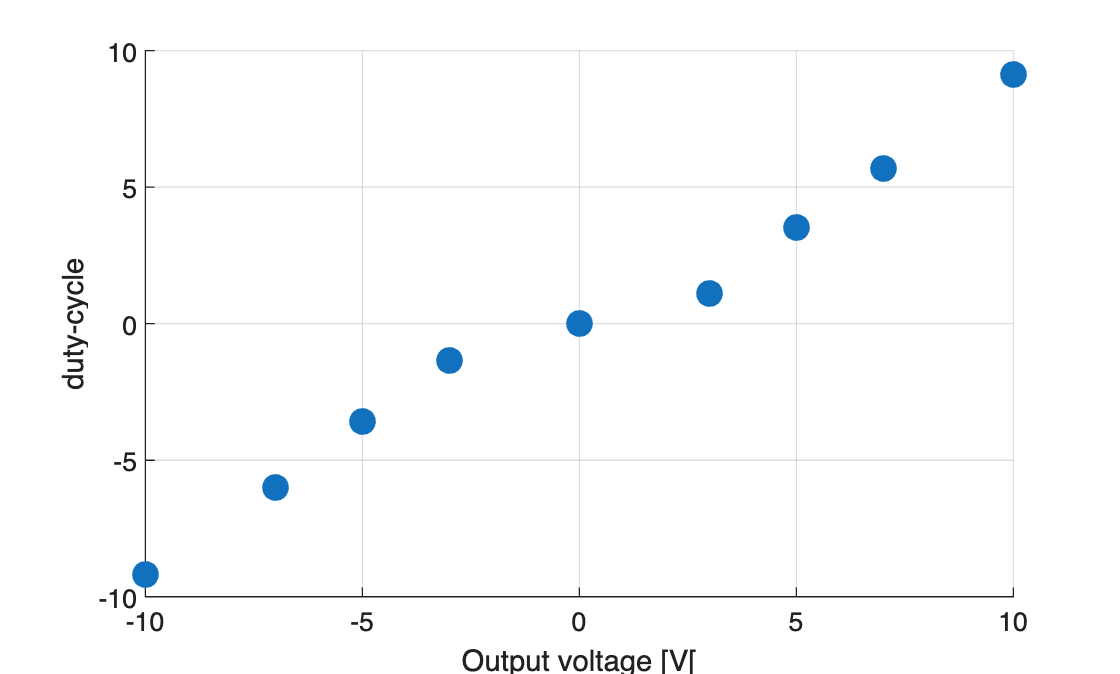

% V_in, V_out
data_calib_out1 = [
    -10, -9.2;
    -7, -6;
    -5, -3.6;
    -3, -1.34; 
    0, -0.01;
    3, 1.1;
    5, 3.53;
    7, 5.7;
    10, 9.12;
    ];

x = data_calib_out1(:,1); % Actual voltage
y = data_calib_out1(:,2); % ADC Integer


figure(3)
scatter(x,y,100,"filled")
grid
xlabel('Output voltage [V[')
ylabel('duty-cycle')

## W_m2 calibration

data_calib_out1 = [
    -10, -8.3;
    -7, -5.1;
    -5, -2.9;
    -3, -0.8; 
    0, -0.04;
    3, 1.3;
    5, 3.5;
    7, 5.7;
    10, 9.12;
    ];


## theta calibration

% degrees, voltage
data_calib_out1 = [
    -10, -13.7;
    -0, -0.9;
    10, 14.7;
    ];
